# Rendering a Scene Using a Simulated Camera

This example renders the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

It includes illustrating how to set the focus distance, and it shows the depth of field for a specific double-Gauss lens.

## Initialize ISETCam and verify Docker installation

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the ChessSet Scene

thisR = piRecipeDefault('scene name','ChessSet');

Read 1 materials.
Read 1 textures.
***Scene parsed.


thisR.set('spatial resolution',512);

## Create a camera with a double Gaussian lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);


Set the distance that will be in focus to .8 meters

thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene aren't obvious. In this case a rotation in x aims the camera lower.

piCameraRotate(thisR, 'x rot',-10);

It's helpful to understand the components of a recipe. Here we show a summary of the recipe information.  There is a lot for this scene.  Take your time working through it:

thisR.summarize;


File information
-----------
Input:  C:\iset\iset3d\data\V3\ChessSet\ChessSet.pbrt
Output: C:\iset\iset3d\local\ChessSet\ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera parameters
-----------
Sub type: omni
Lens file name:   C:\iset\iset3d\data\lens\dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000
Field of view (deg):	28.449267

Film parameters
-----------
subtype: image
x,y resolution: 512 512 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.102 0.466
up:	0.000 1.000 0.000
object distance: 1.006 (m)
                                                  material             positions (m)           sizes (m)     
                                            ____________________    ___________________    __________________

    0003ID_001_mes

## Write and Render

We use the piWRS function to Write out our recipe (as pbrt needs to read from files), Render it via pbrt's ray-tracing, and then Show it so we can visualize it. Here we are specifying that we want to calculate the radiance of the scene.

Overwriting PBRT file C:\iset\iset3d\local\ChessSet\ChessSet.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm -w /ChessSet -v C:/iset/iset3d/local/ChessSet:/ChessSet vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/ChessSet.dat ChessSet.pbrt
*** Rendering time for ChessSet:  46.2 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


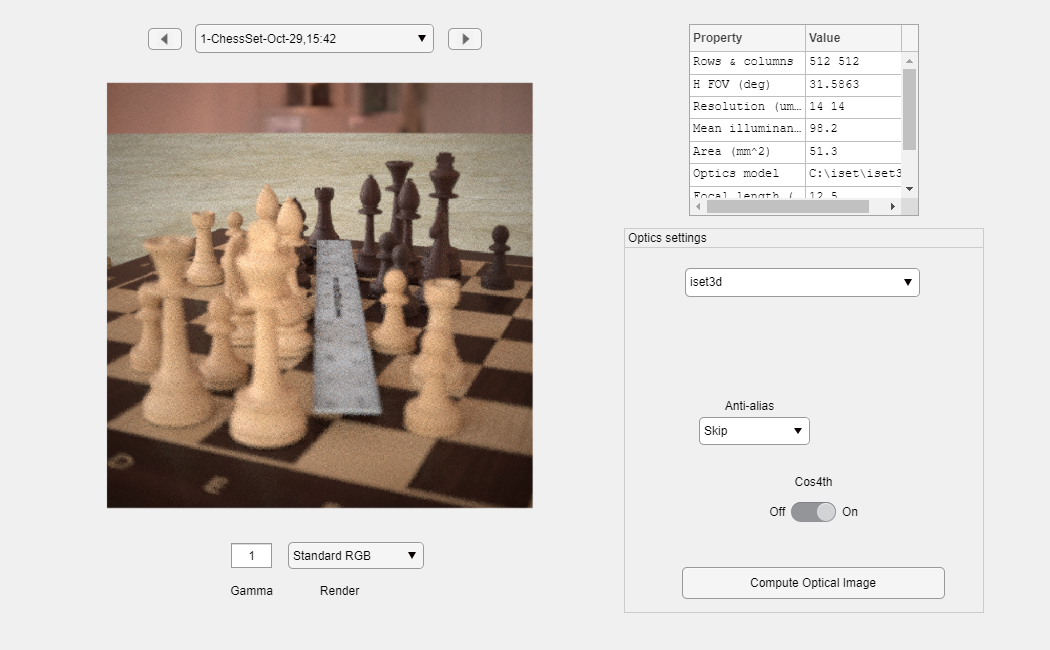

piWRS(thisR,'render type','radiance'); 

## Change the focus distance to 0.4m

Overwriting PBRT file C:\iset\iset3d\local\ChessSet\ChessSet.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm -w /ChessSet -v C:/iset/iset3d/local/ChessSet:/ChessSet vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/ChessSet.dat ChessSet.pbrt
*** Rendering time for ChessSet:  56.3 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


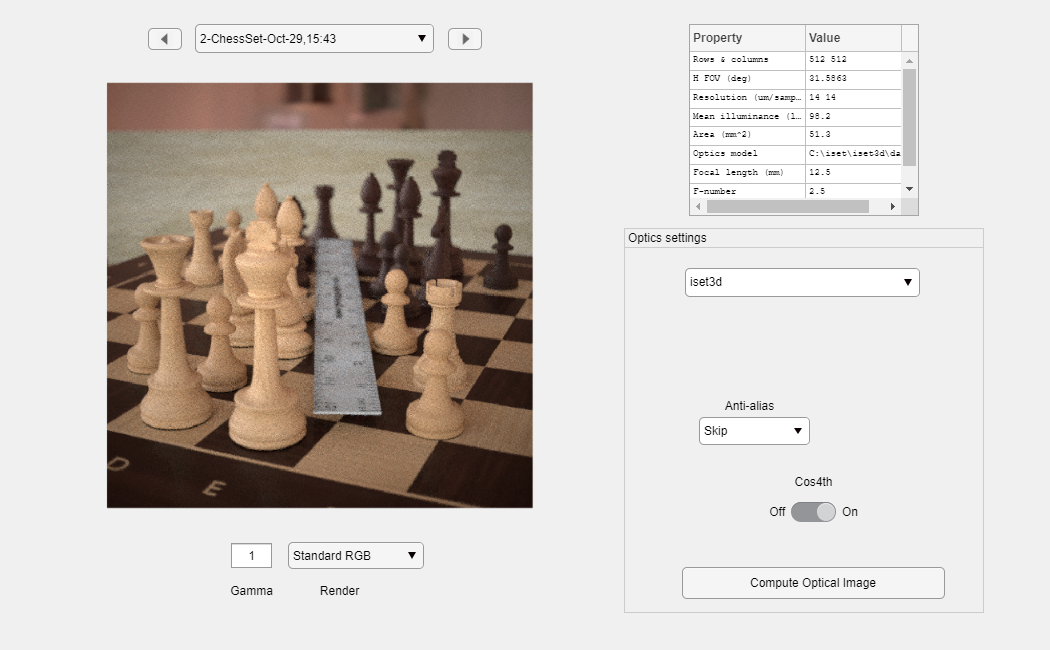

thisR.set('focus distance',0.4);
piWRS(thisR,'render type','radiance'); 